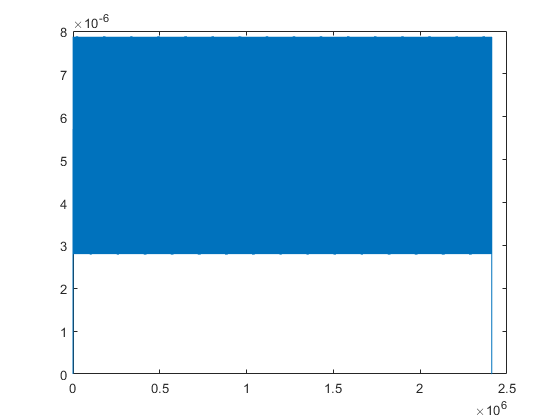

% load('G.mat');
% load('SOS.mat');

y_t = sig_rx ;
figure;plot(y_t)


f_source = 2.412 * (10 ^ 4);
fs = f_source * 10;

fx = 1;

A = 1000;
E = 2 * A;
%采样点数 10s
N = length(y_t);
n = 0 : N-1;
%时间序列
% global t;
t = n / fs ;

y_0 = A * sin(2 * pi * f_source * t) + E;

% y_u = y_0 .* y_t;
% y_u = y_t;
y_u =  sig_dir .* y_t;


[b,a]=sos2tf(SOS,G);
y_fil=filter(b,a, y_u * 1);



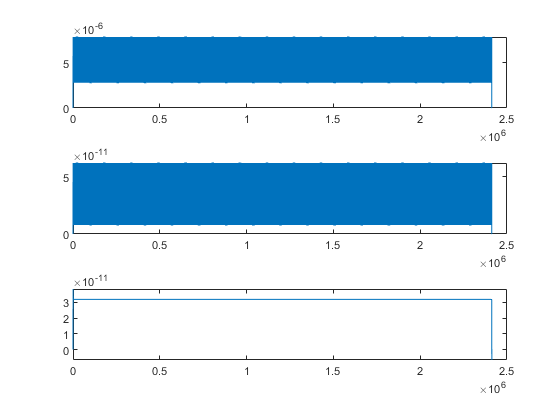

figure
subplot(3,1,1);
plot(y_t * 1);

subplot(3,1,2)
plot(y_u);

subplot(3,1,3)
plot(y_fil);

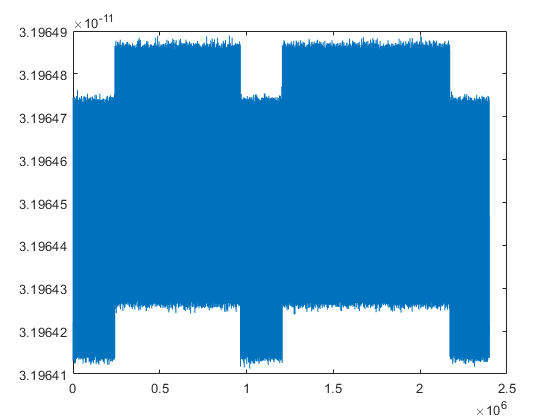

figure;
plot(y_fil(1,1000:2400000));

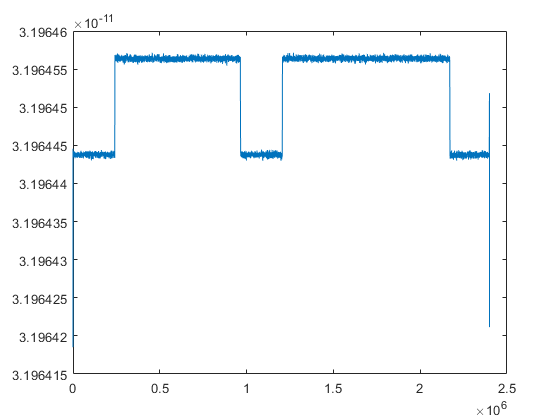

y_v = y_fil(1,1000:2400000);
figure;
plot(smooth(y_v, 800));